% clc; clear;
% 
% Y_clean = [
%      50   80  120  150;
%      60   90  130  160;
%      70  100  140  170;
%      80  110  150  180 ];

Transmission & airlight

% t = 0.6;
% A = 200;

Farword haze model

% X_hazy = t * Y_clean + (1 - t) * A

uncertainty in transmission

% t_guesses = [0.5, 0.58, 0.7];
% num = length(t_guesses);
% 
% Y_p = zeros(size(Y_clean,1), size(Y_clean,2), num);
% 
% for k = 1:num
%     tk = t_guesses(k);
%     Y_p(:,:,k) = (X_hazy - (1 - tk) * A) / tk;
% end

Fusion

% Y_fused = mean(Y_p, 3);

Result

% disp('Clean image Y (ground truth):')
% disp(Y_clean)
% disp('Hazy image X:')
% disp(X_hazy)
% disp('Dehazed samples:')
% for k = 1:num
%     fprintf('Sample %d:\n', k);
%     disp(Y_p(:,:,k))
% end
% disp('Final fused result:')
% disp(Y_fused)

# Uncertainity Aware Image Dehazing

clc; clear; close all;

Read Image

I = im2double(imread("D:\Downloads\Haze1k\Haze1k\Haze1k_thin\dataset\train\input\53-inputs.png"));
% I = im2double(imread("D:\Downloads\Haze1k\Haze1k\Haze1k_thick\dataset\train\input\53-inputs.png"));
assert(size(I,3)==3,'Input must be RGB');

[h,w,~] = size(I)

h = 512

w = 512

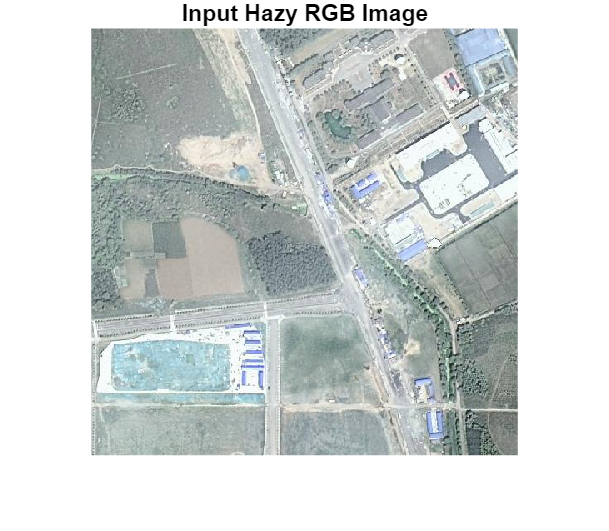


figure; imshow(I); title('Input Hazy RGB Image');

AirLight Estimation

I_gray = rgb2gray(I);
sortedPixels = sort(I_gray(:),'descend');
topPixels = sortedPixels(1:round(0.001*numel(sortedPixels)));
A_gray = mean(topPixels);
A = [A_gray A_gray A_gray];

Transmission Estimation

W = fspecial('average',[15 15]);
t0 = 1 - imfilter(I_gray, W, 'replicate');

Stabilize transmission

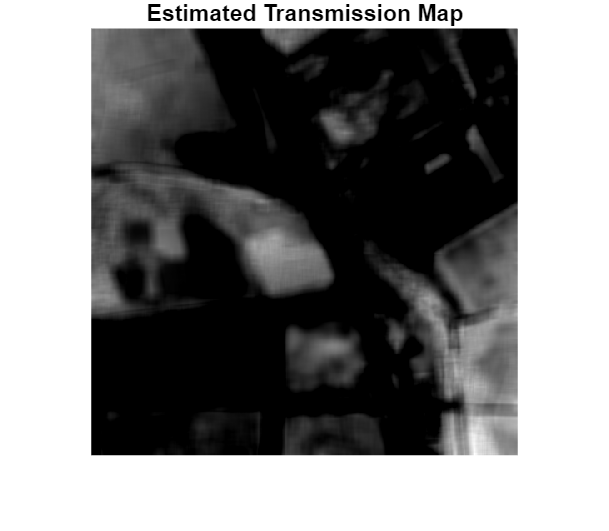

t0 = min(max(t0,0.3),0.9);

figure; imshow(t0,[]); title('Estimated Transmission Map');

CVAE-style uncertainty sampling

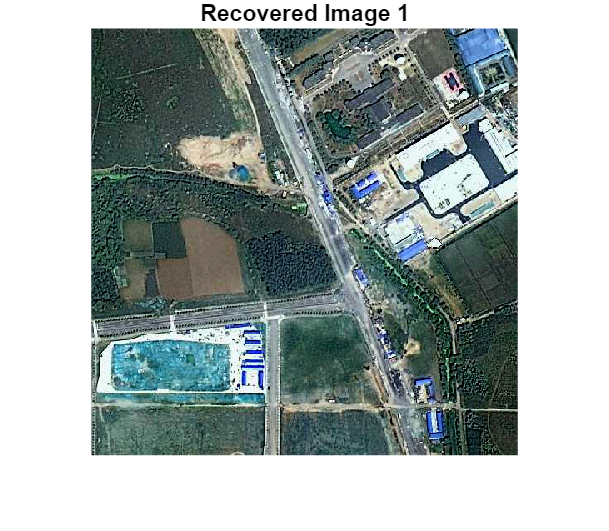

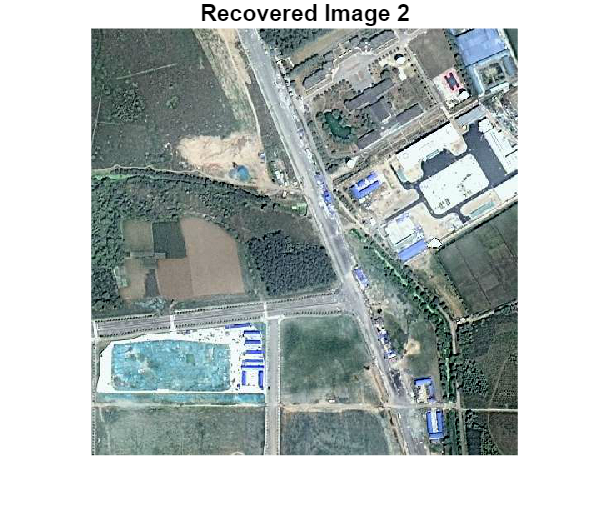

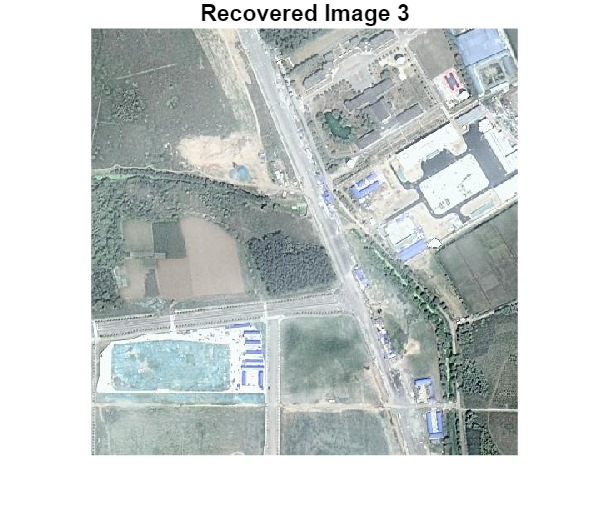

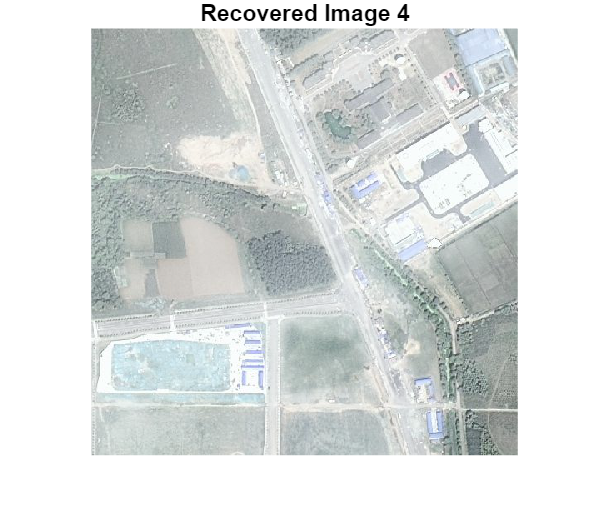

numSamples = 4;
lambdaSet = [0.05 0.10 0.20 0.35];
blurSet   = [5 11 21 31];

Jset = zeros(h,w,3,numSamples);

for k = 1:numSamples

    % Transmission variation
    Wk = fspecial('average',[blurSet(k) blurSet(k)]);
    tk = 1 - imfilter(I_gray, Wk, 'replicate');
    tk = min(max(tk,0.25),0.95);

    lambda = lambdaSet(k);

    % ===== EXACT PSEUDO-INVERSE (SCALAR CASE) =====
    H_pinv = tk ./ (tk.^2 + lambda);

    for c = 1:3
        Jset(:,:,c,k) = H_pinv .* (I(:,:,c) - A(c)) + A(c);
    end

    Jset(:,:,:,k) = min(max(Jset(:,:,:,k),0),1);

    figure;
    imshow(Jset(:,:,:,k));
    title(['Recovered Image ',num2str(k)]);
end

Fusion

Ffused = zeros(h,w,3);

for c = 1:3
    Fsum = zeros(h,w);
    for k = 1:numSamples
        Fsum = Fsum + fft2(Jset(:,:,c,k));
    end
    Ffused(:,:,c) = real(ifft2(Fsum / numSamples));
end

Ffused = min(max(Ffused,0),1);

RGB Correction

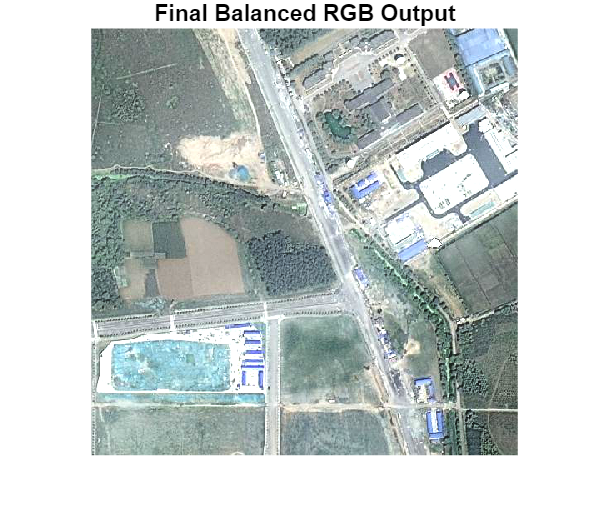

meanRGB_I = squeeze(mean(mean(I,1),2));
meanRGB_J = squeeze(mean(mean(Ffused,1),2));

scale = meanRGB_I ./ meanRGB_J;
scale = min(max(scale,0.9),1.1);

for c = 1:3
    Ffused(:,:,c) = Ffused(:,:,c) * scale(c);
end

Ffused = min(max(Ffused,0),1);

figure;
imshow(Ffused);
title('Final Balanced RGB Output');

Result

imwrite(Ffused,'final_dehazed_rgb.png');
disp('Output saved');

Output saved
